
% clc;

clear all;

global M;

global N;

global Ximage;

global Yimage;

global sy;

Ximage=double(imread('lena.jpg'));
% Ximage = Ximage*256;

key1=0.1;

key=4;

[M,N]=size(Ximage);

subplot(2,2,1)

imshow(Ximage,[]);
title('原图像');

Ximage=double(Ximage);

for(i=1:M)

for(j=1:N)

key1=key*key1*(1-key1);

a(i,j)=key1;

end

end

key2=0.2;

for(i=1:M)

for(j=1:N)

key2=key*key2*(1-key2);

b(i,j)=key2;

end

end

x=0.4*a+0.6*b;

e=round(x*256);

tt=0.01;

Yimage=(tt*Ximage+(1-tt)*e);

subplot(2,2,2)

imshow(Yimage,[]);
title('加密后的图像');


subplot(2,2,3)

imhist(uint8(Ximage));

title('原图像的直方图');

subplot(2,2,4)

imhist(uint8(Yimage));

title('加密之后的直方图');




%%置乱度分析

Yimage=double(Yimage);

sx=sum(sum((Ximage-256*rand(M,N)).^2));
sy=sum(sum((Yimage - 256*rand(M,N)).^2));

DD=sy/sx %置乱度

global M;

global N;

global Ximage;

global Yimage;

% key1=input('请输入密钥key1：');
key1=0.1;

key=4;

for(i=1:M)

for(j=1:N)

key1=key*key1*(1-key1);

a(i,j)=key1;

end

end

% key2=input('请输入密钥key2：');
key2=0.2;

for(i=1:M)

for(j=1:N)

key2=key*key2*(1-key2);

b(i,j)=key2;

end

end

x=0.4*a+0.6*b;

e=round(x*256);

tt=0.01;

Zimage=(Yimage-(1-tt)*e)/tt;

figure(5)

imshow(Zimage,[]);



% 步骤1：读取图像并转换为灰度图
originalImg = imread('水印(二值).bmp');      % 替换为你的图像路径
if size(originalImg, 3) == 3
    originalImg = rgb2gray(originalImg);
end
% originalImg = imresize(originalImg, [64 64]); % 统一尺寸
figure, imshow(originalImg), title('原始图像');

% 步骤2：设置Logistic映射参数（密钥）
x0 = 0.5;      % 初始值（密钥1）
mu = 3.99;      % 控制参数（密钥2）
iterations = 200; % 预热迭代次数（丢弃初始不稳定值）
N = numel(originalImg); % 图像像素总数

% 步骤3：生成混沌序列
% rng(0); % 固定随机种子（仅为演示，实际应避免）
x = x0;
for i = 1:iterations
    x = mu * x * (1 - x); % 预热
end

chaosSeq = zeros(1, N);
for i = 1:N
    x = mu * x * (1 - x);
    chaosSeq(i) = x;
end

% 步骤4：二值化混沌序列（阈值0.5）
binarySeq = chaosSeq > 0.5;

% 步骤5：图像加密（按位异或）
encryptedImg = originalImg;
encryptedImg(:) = bitxor(originalImg(:), binarySeq');

% 显示加密结果
figure, imshow(encryptedImg), title('加密后的图像');


decryptedImg = encryptedImg;
decryptedImg(:) = bitxor(encryptedImg(:), (binarySeq') );
figure, imshow(decryptedImg), title('解密后的图像');

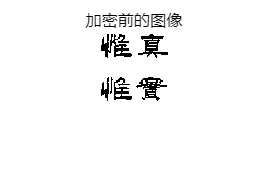

close all
clc
clear

originalImg = imread('水印(二值).bmp');    
figure, imshow(originalImg), title('加密前的图像');

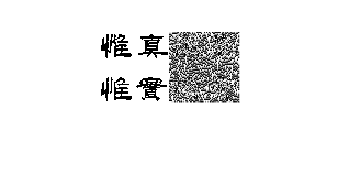

originalImg=uint8(originalImg*255);

v=lock_logistic_gray(originalImg,0.1,4);

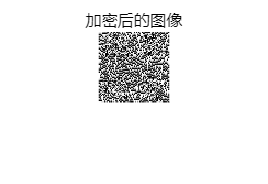


figure, imshow(v), title('加密后的图像');

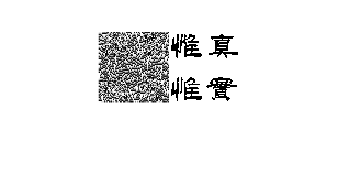


vv = unlock_logistic_gray(v, 0.1, 4);

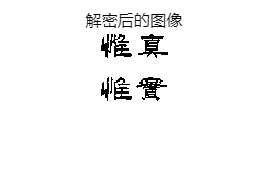

figure, imshow(vv), title('解密后的图像');

%利用Logistic混沌映射，对灰度图像进行序列加密


function v=lock_logistic_gray(picture,x0,u)
[M,N]=size(picture);
x=x0;
%迭代500次，达到充分混沌状态
for i=1:500
    x=u*x*(1-x);
end
%产生一维混沌加密序列
A=zeros(1,M*N);
A(1)=x;
for i=1:M*N-1
A(i+1)=u*A(i)*(1-A(i));
end
%归一化序列
B=uint8(255*A);
%转化为二维混沌加密序列
Fuck=reshape(B,M,N);
Rod=bitxor(picture,Fuck);%异或操作加密
v=Rod;
figure;
imshow([picture,v]);
end
%完

function v = unlock_logistic_gray(encrypted_pic, x0, u)
[M, N] = size(encrypted_pic);
x = x0;
% 迭代500次达到混沌状态
for i = 1:500
    x = u * x * (1 - x);
end
% 生成一维混沌序列
A = zeros(1, M*N);
A(1) = x;
for i = 1:M*N-1
    A(i+1) = u * A(i) * (1 - A(i));
end
% 归一化并转为二维加密矩阵
B = uint8(255 * A);
Fuck = reshape(B, M, N);
% 异或操作解密
decrypted_pic = bitxor(encrypted_pic, Fuck);
v = decrypted_pic;
figure;
imshow([encrypted_pic, v]); % 显示加密图和解密结果
end